## **Worked Example 8.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input dynamics matrix and calculate its eigenvalues
A = [0 1 0 0; 0 0 -5 0; 0 0 0 1; -5 0 0 0];
eig(A)

ans =   -2.2361 + 0.0000i
  -0.0000 + 2.2361i
  -0.0000 - 2.2361i
   2.2361 + 0.0000i


% Input the remaining matrices and create a state-space system
B = [0; 0; 0; 1 / 8];
C = [1 0 0 0];
D = [0];
sys = ss(A, B, C, D);

% Compute the reachability matrix of the system and compute its determinant 
Wr = ctrb(sys)

Wr =          0         0         0   -0.6250
         0         0   -0.6250         0
         0    0.1250         0         0
    0.1250         0         0         0


det(Wr)

ans = 0.0061


% Create a vector of the desired eigenvalue locations 
P = [-20; -30; (-4 + 3i); (-4 - 3i)];

% Calculate the state feedback gain vector K
K = -1 * place(A, B, P)

K = 1.0e+04 *

    2.4040    0.9680   -0.8200   -0.0464



% Create a closed-loop dynamics matrix
Acl = A + B * K;

% Calculate the feedforward gain kr
kr = -1/(C * inv(Acl) * B)

kr = -2.4000e+04

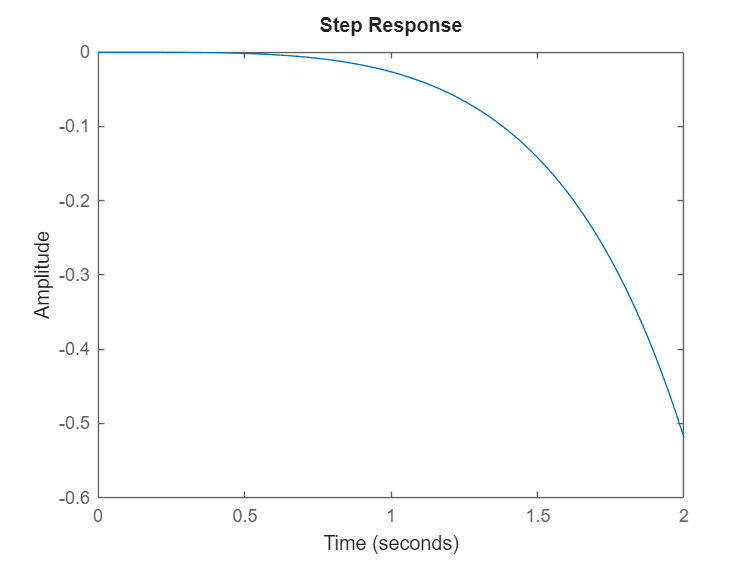


% Create a closed-loop system 
sys_cl = ss(Acl, B * kr, C, D);

% Check step response
step(sys, 2)

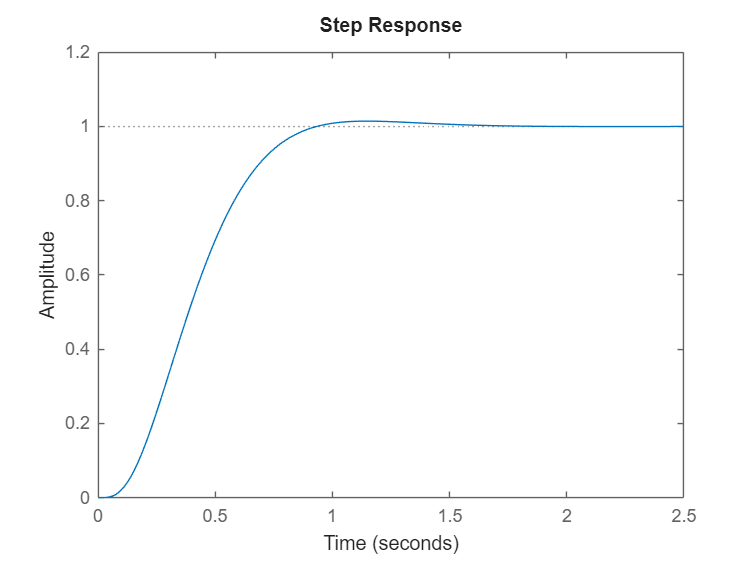

step(sys_cl, 2.5)